# General variables

## Simulation variables

SNRdB = 10;                % SNR in dB

totalNoSlots = 3;          % Number slots containing information simulated

perfectEstimation = false; % Perfect synchronization and channel estimation
rng("default");            % Set default random number generator for repeatability

fileID = fopen('Bits.bin','r'); %send bit file
fileID2 = fopen('RecBits.bin','w'); %recieve bit file

## Carrier config

carrier = nrCarrierConfig

carrier =   nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 15
           CyclicPrefix: 'normal'
              NSizeGrid: 52
             NStartGrid: 0
                  NSlot: 0
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 1
          SlotsPerFrame: 10


carrier.NCellID = 1;
carrier.SubcarrierSpacing = 15;
carrier.CyclicPrefix = 'normal';
carrier.NSizeGrid;
carrier.NSlot;
carrier.NFrame;
carrier.IntraCellGuardBands;

%Read-Only variables
%SymbolsPerSlot: Number of OFDM symbols per slot bases on CyclePrefix
%SlotsPerSubFrame: Number of Slots per 1ms frame, based of the subcarrierspacing
%SlotsPerFrame: Number of Slots per 10ms frame, based of the subcarrierspacing


## Physical Downlink Shared Channel

pdsch = nrPDSCHConfig;
pdsch.NSizeBWP;
pdsch.NStartBWP;
pdsch.ReservedPRB;
pdsch.ReservedRE;
pdsch.Modulation = "16QAM";
pdsch.NumLayers = 1;
pdsch.MappingType;
pdsch.SymbolAllocation;
pdsch.PRBSet = 0:carrier.NSizeGrid-1;     % Full band allocation
pdsch.PRBSetType;
pdsch.VRBToPRBInterleaving;
pdsch.VRBBundleSize;
pdsch.NID;
pdsch.RNTI;
pdsch

pdsch =   nrPDSCHConfig with properties:

                NSizeBWP: []
               NStartBWP: []
             ReservedPRB: {[1×1 nrPDSCHReservedConfig]}
              ReservedRE: []
              Modulation: '16QAM'
               NumLayers: 1
             MappingType: 'A'
        SymbolAllocation: [0 14]
                  PRBSet: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51]
              PRBSetType: 'VRB'
    VRBToPRBInterleaving: 0
           VRBBundleSize: 2
                     NID: []
                    RNTI: 1
                    DMRS: [1×1 nrPDSCHDMRSConfig]
              EnablePTRS: 0
                    PTRS: [1×1 nrPDSCHPTRSConfig]

   Read-only properties:
            NumCodewords: 1


## PDSCH-DeModulation Refrence Signal

pdsch.DMRS.DMRSConfigurationType = 1;
pdsch.DMRS.DMRSReferencePoint;
pdsch.DMRS.DMRSTypeAPosition; 
pdsch.DMRS.DMRSAdditionalPosition;
pdsch.DMRS.DMRSLength = 2;
pdsch.DMRS.CustomSymbolSet; 
pdsch.DMRS.DMRSPortSet;
pdsch.DMRS.NIDNSCID; 
pdsch.DMRS.NSCID; 
pdsch.DMRS.NumCDMGroupsWithoutData;
pdsch.DMRS.DMRSDownlinkR16;
pdsch.DMRS.CDMGroups;
pdsch.DMRS.DeltaShifts;
pdsch.DMRS.FrequencyWeights;
pdsch.DMRS.TimeWeights;
pdsch.DMRS.DMRSSubcarrierLocations;
pdsch.DMRS.CDMLengths;
pdsch.DMRS

ans =   nrPDSCHDMRSConfig with properties:

      DMRSConfigurationType: 1
         DMRSReferencePoint: 'CRB0'
          DMRSTypeAPosition: 2
     DMRSAdditionalPosition: 0
                 DMRSLength: 2
            CustomSymbolSet: []
                DMRSPortSet: []
                   NIDNSCID: []
                      NSCID: 0
    NumCDMGroupsWithoutData: 2
            DMRSDownlinkR16: 0

   Read-only properties:
                  CDMGroups: 0
                DeltaShifts: 0
           FrequencyWeights: [2×1 double]
                TimeWeights: [2×1 double]
    DMRSSubcarrierLocations: [6×1 double]
                 CDMLengths: [1 1]


## DL-SCH Configuration

NHARQProcesses = 1;     % Number of parallel HARQ processes
rvSeq = [0 2 3 1];              % 0 = disabled HARQ retransmission incase of an error

% Coding rate
if pdsch.NumCodewords == 1 
    codeRate = 490/1024; %For up to 4 layers 
else
    codeRate = [490 490]./1024; %For above 4 layers
end


% Create DL-SCH encoder object
encodeDLSCH = nrDLSCH;
encodeDLSCH.MultipleHARQProcesses = true;
encodeDLSCH.TargetCodeRate = codeRate;

% Create DLSCH decoder object
decodeDLSCH = nrDLSCHDecoder;
decodeDLSCH.MultipleHARQProcesses = true;
decodeDLSCH.TargetCodeRate = codeRate;
decodeDLSCH.LDPCDecodingAlgorithm = "Normalized min-sum";
decodeDLSCH.MaximumLDPCIterationCount = 6;

## HARQ Management

harqEntity = HARQEntity(0:NHARQProcesses-1,rvSeq,pdsch.NumCodewords);

## Channel Configuration

nTxAnts = 1;
nRxAnts = 1;

% Check that the number of layers is valid for the number of antennas
if pdsch.NumLayers > min(nTxAnts,nRxAnts)
    error("The number of layers ("+string(pdsch.NumLayers)+") must be smaller than min(nTxAnts,nRxAnts) ("+string(min(nTxAnts,nRxAnts))+")")
end

channel = nrTDLChannel;
channel.DelayProfile = "TDL-C";
channel.NumTransmitAntennas = nTxAnts;
channel.NumReceiveAntennas = nRxAnts;

ofdmInfo = nrOFDMInfo(carrier);
channel.SampleRate = ofdmInfo.SampleRate;
channel

channel =   nrTDLChannel with properties:

                 DelayProfile: 'TDL-C'
                  DelaySpread: 3.0000e-08
          MaximumDopplerShift: 5
                   SampleRate: 15360000
              MIMOCorrelation: 'Low'
                 Polarization: 'Co-Polar'
        TransmissionDirection: 'Downlink'
          NumTransmitAntennas: 1
           NumReceiveAntennas: 1
           NormalizePathGains: true
                  InitialTime: 0
                 NumSinusoids: 48
                 RandomStream: 'mt19937ar with seed'
                         Seed: 73
      NormalizeChannelOutputs: true
             ChannelFiltering: true
    TransmitAndReceiveSwapped: false


## Transmission and Reception

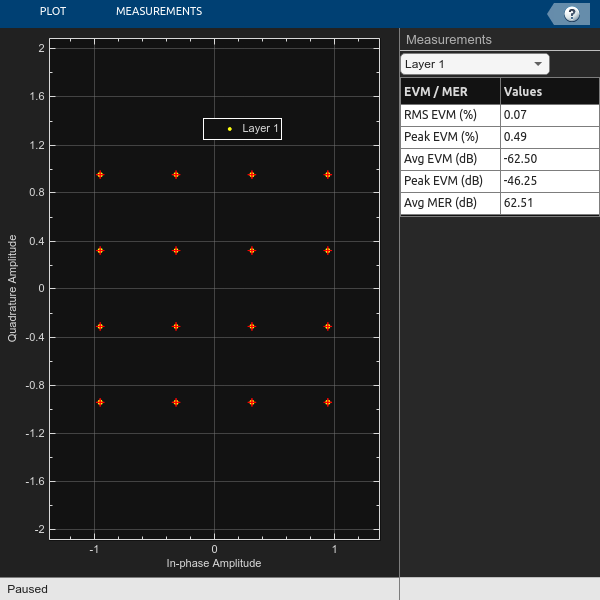

trBlk =      1
     0
     1
     0
     1
     0
     1
     0
     1
     0


Slot 0. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   0
   1
   0
   1
   0
   1
   0
   1
   0


pass = logical
   1


trBlk =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Slot 1. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


pass = logical
   1


trBlk =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


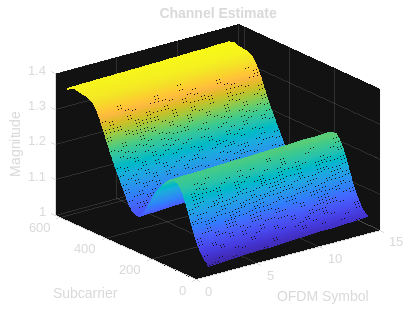

Slot 2. HARQ Proc 0: CW0: Initial transmission passed (RV=0,CR=0.478900).


decbits = 14344×1 int8 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


pass = logical
   1


constPlot = comm.ConstellationDiagram;                                          % Constellation diagram object
constPlot.ReferenceConstellation = getConstellationRefPoints(pdsch.Modulation); % Reference constellation values
constPlot.EnableMeasurements = 1;                                               % Enable EVM measurements

% Initial timing offset
offset = 0;

estChannelGrid = getInitialChannelEstimate(channel,carrier);
newPrecodingWeight = getPrecodingMatrix(pdsch.PRBSet,pdsch.NumLayers,estChannelGrid);

for nSlot = 0:totalNoSlots-1
     carrier.NSlot = nSlot;

    [txWaveform, waveformInfo, trBlk, trBlkSizes] = TranmitterEntity(carrier, pdsch, encodeDLSCH, harqEntity, nSlot, newPrecodingWeight, codeRate, fileID, nTxAnts, decodeDLSCH);

    trBlk

    chInfo = info(channel);
    maxChDelay = chInfo.MaximumChannelDelay;
    txWaveform = [txWaveform; zeros(maxChDelay,size(txWaveform,2))];
    
    [rxWaveform,pathGains,sampleTimes] = channel(txWaveform);
    %noise = generateAWGN(SNRdB,nRxAnts,waveformInfo.Nfft,size(rxWaveform));
    %rxWaveform = rxWaveform + noise;

    [decbits, statusReport, pdschEq] = RecieverEntity(carrier, pdsch, decodeDLSCH, harqEntity, rxWaveform, offset, fileID2, newPrecodingWeight, trBlkSizes);
    disp("Slot "+(nSlot)+". "+statusReport);
    decbits

    constPlot.ChannelNames = "Layer "+(pdsch.NumLayers:-1:1);
    constPlot.ShowLegend = true;
    % Constellation for the first layer has a higher SNR than that for the
    % last layer. Flip the layers so that the constellations do not mask
    % each other.
    constPlot(fliplr(pdschEq));

    if decbits == trBlk
        pass = true
    else
        pass = false    
    end
 
end

## Local Functions

function wtx = getPrecodingMatrix(PRBSet,NLayers,hestGrid)
% Calculate precoding matrix given an allocation and a channel estimate
    
    % Allocated subcarrier indices
    allocSc = (1:12)' + 12*PRBSet(:).';
    allocSc = allocSc(:);
    
    % Average channel estimate
    [~,~,R,P] = size(hestGrid);
    estAllocGrid = hestGrid(allocSc,:,:,:);
    Hest = permute(mean(reshape(estAllocGrid,[],R,P)),[2 3 1]);
    
    % SVD decomposition
    [~,~,V] = svd(Hest);
    
    wtx = V(:,1:NLayers).';
    wtx = wtx/sqrt(NLayers); % Normalize by NLayers
end

function estChannelGrid = getInitialChannelEstimate(channel,carrier)
% Obtain an initial channel estimate for calculating the precoding matrix.
% This function assumes a perfect channel estimate

    % Clone of the channel
    chClone = channel.clone();
    chClone.release();

    % No filtering needed to get channel path gains
    chClone.ChannelFiltering = false;    
    
    % Get channel path gains
    [pathGains,sampleTimes] = chClone();
    
    % Perfect timing synchronization
    pathFilters = getPathFilters(chClone);
    offset = nrPerfectTimingEstimate(pathGains,pathFilters);
    
    % Perfect channel estimate
    estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);
end

function refPoints = getConstellationRefPoints(mod)
% Calculate the reference constellation points for a given modulation
% scheme.
    switch mod
        case "QPSK"
            nPts = 4;
        case "16QAM"
            nPts = 16;
        case "64QAM"
            nPts = 64;
        case "256QAM"
            nPts = 256;            
    end
    binaryValues = int2bit(0:nPts-1,log2(nPts));
    refPoints = nrSymbolModulate(binaryValues(:),mod);
end
